## **Computing a surface from spherical harmonic expansion**

   We know that any surface is characterized by two parameters, ex. u and v. So if the surface is continuous we can represent x,y,z coordinates of that surface by: x=x(u,v), y=y(u,v), and z=z(u,v). We take the parameters to be zenith and azimuthal angels in spherical coordinate system ( u = $\theta$, and v=$\varphi$) to describe a general surface. Therefore, in Cartesian coordinates the surface is described as $x=x(\theta,\varphi)$, $y=y(\theta,\varphi)$, and $z=z(\theta,\varphi)$. Also, the surface in spherical coordinate  would be $\theta = \theta$,$\varphi = \varphi$, $r=r(\theta,\varphi)$. For example, the equation of a sphere with radius $R$ will be $\theta = \theta$, $\varphi = \varphi$, $r=R$.

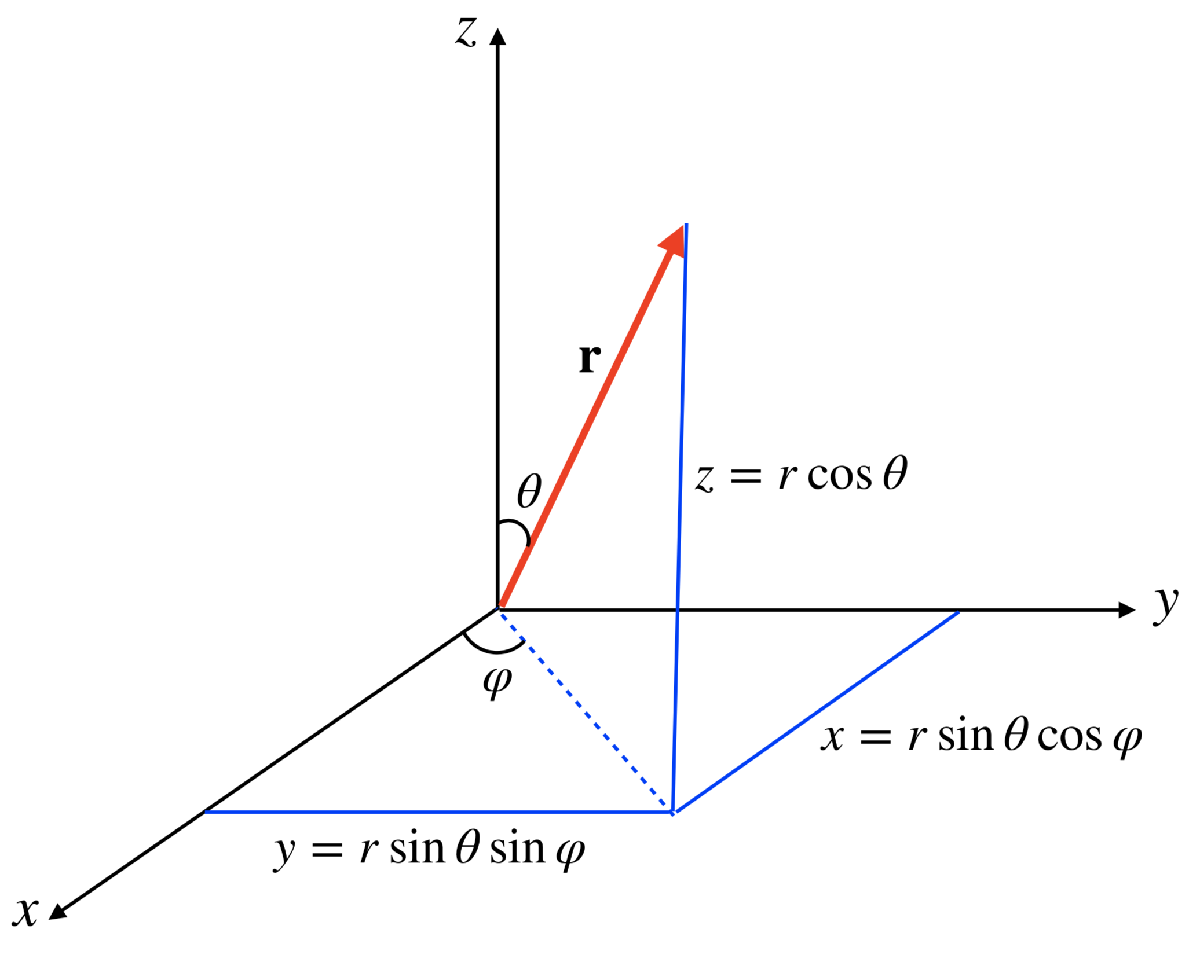

The spherical harmonics are defined as $Y_{\ell}^{m} (\theta,\varphi) = N_{\ell,m} \, P_{\ell}^{|m|} (\cos\theta) \,{\mathrm{e}}^{im\varphi}$.

 $N_{\ell,m}$ is normalization prefactor, which is equal to $N_{\ell,m} = \sqrt{\frac{2\ell +1}{4\pi} \frac{(\ell -m)!}{(\ell +m)!}} $,  and 

$N_{\ell,-m} = {(-1)}^{m}\sqrt{\frac{2\ell +1}{4\pi} \frac{(\ell -m)!}{(\ell +m)!}} $ , ($m>0$).

   $P_{\ell}^{m} (\cos\theta)$ is associate Legendre function. We have ($m>0$): $P_{\ell}^{-m} (\cos\theta) = {(-1)}^{m} \frac{(\ell -m)!}{(\ell + m)!} P_{\ell}^{m} (\cos\theta)$. So:


$$Y_{\ell}^{-m} (\theta,\varphi) = \sqrt{\frac{2\ell +1}{4\pi}\frac{(\ell+m)!}{(\ell -m)!}} {(-1)}^m \frac{(\ell-m)!}{(\ell+m)!} P_{\ell}^{m}(\cos\theta) \, {\mathrm{e}}^{-im\varphi} = N_{\ell,-m} P_{\ell}^{m}(\cos\theta)  \, {\mathrm{e}}^{-im\varphi} $$


 The spherical harmonics form a complete basis set in Hilbert space of square integrable functions, and are normalized and orthogonal: $\int_{0}^{2\pi} \int_{0}^{\pi} Y_{\ell_1 ,m_1} (\theta,\varphi) Y_{\ell_2 ,m_2}^{*} (\theta ,\varphi) \sin\theta \,\,\mathrm{d}\theta \,\,\mathrm{d}\varphi = {\delta}_{\ell_1 ,\ell_2} {\delta}_{m_1 , m_2}$, where ${\delta}_{a,b} $ is Kronecker delta function, and $Y_{\ell ,m}^{*}$ is the complex conjugate of $Y_{\ell ,m}$. Any function can be expressed as a linear combination of spherical harmonics:


$$x(\theta , \varphi) = \sum_{\ell =0}^{\infty} \sum_{m=-\ell}^{\ell} a_{\ell ,m}^x Y_{\ell}^{m} (\theta ,\varphi)$$
 
$$\rightarrow$$
 
$$a_{\ell ,m}^x = \int_{0}^{2\pi} \int_{0}^{\pi} x(\theta ,\varphi) Y_{\ell ,m}^{*} (\theta ,\varphi) \,\, \sin\theta \, \mathrm{d} \theta \, \mathrm{d} \varphi$$



$$y(\theta , \varphi) = \sum_{\ell =0}^{\infty} \sum_{m=-\ell}^{\ell} a_{\ell ,m}^y Y_{\ell}^{m} (\theta ,\varphi)$$

$$\rightarrow$$
 
$$a_{\ell ,m}^y = \int_{0}^{2\pi} \int_{0}^{\pi} y(\theta ,\varphi) Y_{\ell ,m}^{*} (\theta ,\varphi) \,\, \sin\theta \, \mathrm{d} \theta \, \mathrm{d} \varphi$$



$$z(\theta , \varphi) = \sum_{\ell =0}^{\infty} \sum_{m=-\ell}^{\ell} a_{\ell ,m}^z Y_{\ell}^{m} (\theta ,\varphi)$$

$$\rightarrow$$
 
$$a_{\ell ,m}^z = \int_{0}^{2\pi} \int_{0}^{\pi} z(\theta ,\varphi) Y_{\ell ,m}^{*} (\theta ,\varphi) \,\, \sin\theta \, \mathrm{d} \theta \, \mathrm{d} \varphi$$


$a_{\ell ,m}^x$, $a_{\ell ,m}^y$, and $a_{\ell ,m}^z$ are the expansion coefficients which we are going to calculate for a given surface.

clc; clear;

N_phi=51; % #grid points in phi coordinates
N_theta=41;  % #grid points in theta coordinates
[s,w_theta]=gauss(N_theta); % creating Gauss points and weights for theta coordinates
phi=linspace(0,2*pi,N_phi)'; % creating uniform points for phi coordinates
dphi=2*pi/(N_phi-1);            
w_phi=ones(N_phi,1)*dphi;   % creating uniform weights for phi coordinates
w_phi(1)=w_phi(1)/2; w_phi(end)=w_phi(end)/2;  % just making weights more accurate
[Phi,S]=meshgrid(phi,s); % making meshgrid of dimension N_theta * N_phi 
Theta=acos(S);  % definition of Gauss points

%a=2; b=1; c=1.5;
%%%%%%%%%% some general surface with bumps on it %%%%%%%%
% X0=(a+0.5*cos(3*Phi).^2.*sin(2*Theta).^2).*cos(Phi).*sin(Theta);
% Y0=(b+0.25*sin(3*Phi).^2.*sin(Theta).^3).*sin(Phi).*sin(Theta);
% Z0=(c+0.5*cos(4*Phi).^2.*sin(3*Theta).^2).*cos(Theta);

% h1=surf(X0,Y0,Z0);alpha(h1,0.25);hold on;axis equal;


Here we create some experimental data for x,y, and z coordinates of a surface, which is described by $\theta$ and $\varphi$ spherical coordinates.

We then fit these experimental data of each coordinate with 'scatteredInterpolant' function; Basicaly, `scatteredInterpolant(`$\theta$`,`$\varphi$`,`$x$`)` creates an interpolant that fits a surface of the form $x = F(\theta , \varphi)$. 

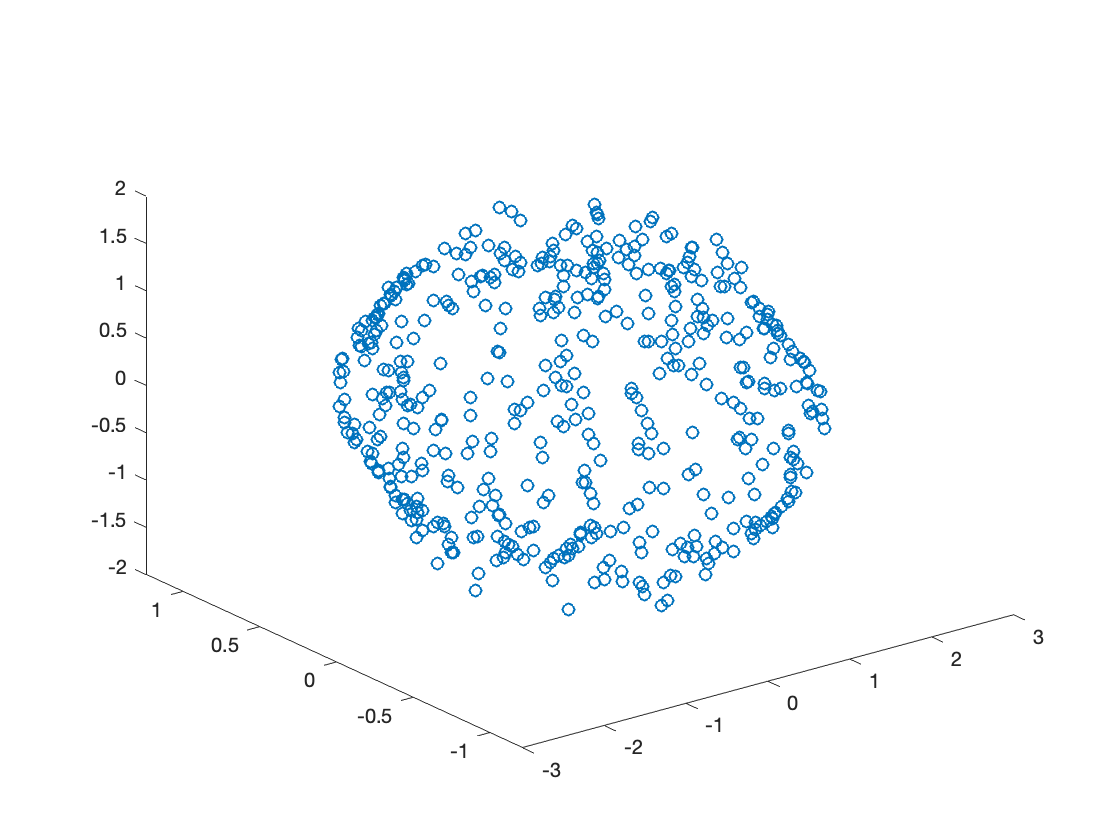

N=500;
phi_exp=2*pi*rand(N,1); % N random numbers btw 0 and 2*pi
s_exp=rand(N,1)*2-1; % N random numbers btw -1 and 1
theta_exp=acos(s_exp);
a=2; b=1; c=1.5;
x_exp=(a+0.5*cos(3*phi_exp).^2.*sin(2*theta_exp).^2).*cos(phi_exp).*sin(theta_exp);
y_exp=(b+0.25*sin(3*phi_exp).^2.*sin(theta_exp).^3).*sin(phi_exp).*sin(theta_exp);
z_exp=(c+0.5*cos(4*phi_exp).^2.*sin(3*theta_exp).^2).*cos(theta_exp);
plot3(x_exp,y_exp,z_exp,'o'); hold on;


sx = scatteredInterpolant(s_exp,phi_exp,x_exp,'linear','nearest');
sy = scatteredInterpolant(s_exp,phi_exp,y_exp,'linear','nearest');
sz = scatteredInterpolant(s_exp,phi_exp,z_exp,'linear','nearest');

X0 = sx(S,Phi);
Y0 = sy(S,Phi);
Z0 = sz(S,Phi);
% 
%h1=surf(X0,Y0,Z0);alpha(h1,0.25);hold on;axis equal; 


Here first we calculate spherical harmonics, Y1 for positove m, and Y2 for negative m. The expansion coefficients ax, ay, az (for positive m), and ax2, ay2, and az2 (for negative m) are calculated by integration. 

The integration is done by summing over the values of the integrand multiplied by weights:


$$\int_{0}^{\pi} \int_{0}^{2\pi} x(\theta ,\varphi) Y_{\ell ,m}^{*} (\theta ,\varphi) \,\sin\theta \mathrm{d}\theta \,\mathrm{d}\varphi = \sum_{i=1}^{N_{\theta}} \sum_{j=1}^{N_{\varphi}} x({\theta}_i ,{\varphi}_j) Y_{\ell ,m}^{*} ({\theta}_i ,{\varphi}_j) \, w_{\theta}^{i} w_{\varphi}^{j}$$


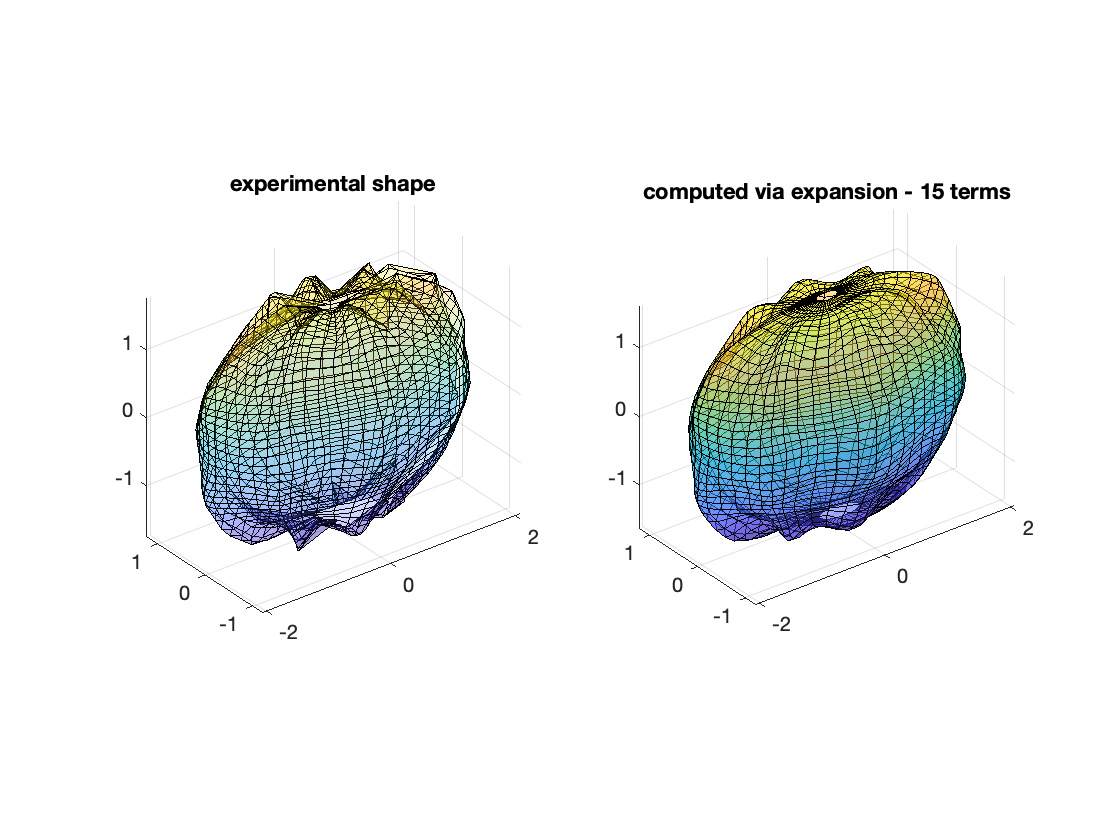

%%%%%%%%%% calculating the shape via spherical harmonic expansion   %%%%%%%%%% 
le=15;   % Upper limit of number of terms in expansion (increase for more accuracy)

Xc=zeros(N_theta,N_phi); % initializing 'computed' coordinate values 
Yc=Xc;Zc=Xc;

for l=0:le
    pl=legendre(l,s)';
    for m=1:l+1
        m0=m-1;
        p=repmat(pl(:,m),1,N_phi); % associated Legendre function
        pref=sqrt((2*l+1)*factorial(l-m0)/(4*pi*factorial(l+m0)));  
        
        Y1=p.*exp(sqrt(-1)*Phi*m0)*pref; % spherical harmonics (positive m0)
        if (m0~=0)
            Y2=p.*exp(-sqrt(-1)*Phi*m0)*((-1)^(m0)*pref);% spherical harmonics (negative m0)
        else
            Y2=zeros(N_theta,N_phi);
        end
      
         Fx=X0.*conj(Y1);
         Fy=Y0.*conj(Y1);
         Fz=Z0.*conj(Y1);
        
         Fx2=X0.*conj(Y2);
         Fy2=Y0.*conj(Y2);
         Fz2=Z0.*conj(Y2);
        
         Qx=w_theta*(Fx*w_phi);
         Qy=w_theta*(Fy*w_phi);
         Qz=w_theta*(Fz*w_phi);
        
         Qx2=w_theta*(Fx2*w_phi);
         Qy2=w_theta*(Fy2*w_phi);
         Qz2=w_theta*(Fz2*w_phi);
   % expansion coefficients for  m > 0 :     
         ax(l+1,m)=Qx;
         ay(l+1,m)=Qy;
         az(l+1,m)=Qz;
   % expansion coefficients for  m < 0 :      
         ax2(l+1,m)=Qx2;
         ay2(l+1,m)=Qy2;
         az2(l+1,m)=Qz2;
   % computed coordinates    
         Xc=Xc+ax(l+1,m)*Y1+ax2(l+1,m)*Y2;
         Yc=Yc+ay(l+1,m)*Y1+ay2(l+1,m)*Y2;
         Zc=Zc+az(l+1,m)*Y1+az2(l+1,m)*Y2;
    end
end

figure;
subplot(1,2,1)
h1=surf(X0,Y0,Z0);alpha(h1,0.25);hold on;axis equal;
title('experimental shape'); 
subplot(1,2,2)
h2=surf((Xc),(Yc),(Zc));alpha(h2,0.5);axis equal;
title(['computed via expansion - ' num2str(le) ' terms'])



%====================================

function [x,w]=gauss(N)
beta=0.50./sqrt(1-(2*(1:N-1)).^(-2));
T=diag(beta,1)+diag(beta,-1);
[V,D]=eig(T);
x=diag(D);[x,i]=sort(x);
w=2*V(1,i).^2;
end
